## 第一部分：MATLAB中的数据类型和数据结构

% 1.1 MATLAB基础数据类型
disp(' ')

disp('=== MATLAB基础数据类型 ===')

=== MATLAB基础数据类型 ===


disp('MATLAB支持多种数据类型，理解这些类型对数据处理至关重要：')

MATLAB支持多种数据类型，理解这些类型对数据处理至关重要：



% 数值类型
disp('1. 数值类型 (Numeric Types):')

1. 数值类型 (Numeric Types):


a_double = 3.14159;  % 双精度浮点数（默认）
a_int = int32(100);   % 32位整数
a_uint = uint8(255);  % 8位无符号整数

disp(['双精度浮点数: ', num2str(a_double), ' (class: ', class(a_double), ')'])

双精度浮点数: 3.1416 (class: double)


disp(['32位整数: ', num2str(a_int), ' (class: ', class(a_int), ')'])

32位整数: 100 (class: int32)


disp(['8位无符号整数: ', num2str(a_uint), ' (class: ', class(a_uint), ')'])

8位无符号整数: 255 (class: uint8)



% 字符和字符串
disp(' ')

disp('2. 字符和字符串 (Characters and Strings):')

2. 字符和字符串 (Characters and Strings):


a_char = 'A';                % 字符
a_string = "Hello MATLAB";   % 字符串
cell_string = {'Apple', 'Banana', 'Cherry'};  % 字符元胞数组

disp(['字符: ', a_char, ' (class: ', class(a_char), ')'])

字符: A (class: char)


disp(['字符串: ', a_string, ' (class: ', class(a_string), ')'])

    "字符串: "    "Hello MATLAB"    " (class: "    "string"    ")"



disp(['字符元胞数组: ', strjoin(cell_string, ', '), ' (class: ', class(cell_string), ')'])

字符元胞数组: Apple, Banana, Cherry (class: cell)



% 逻辑类型
disp(' ')

disp('3. 逻辑类型 (Logical Types):')

3. 逻辑类型 (Logical Types):


a_logical = true;           % 逻辑真
b_logical = (10 > 5);       % 逻辑表达式结果
logical_array = [true, false, true, false];

disp(['逻辑真: ', num2str(a_logical), ' (class: ', class(a_logical), ')'])

逻辑真: 1 (class: logical)


disp(['10 > 5 的结果: ', num2str(b_logical), ' (class: ', class(b_logical), ')'])

10 > 5 的结果: 1 (class: logical)


disp(['逻辑数组: ', num2str(logical_array), ' (class: ', class(logical_array), ')'])

逻辑数组: 1  0  1  0 (class: logical)



% 分类数据类型（美赛常用）
disp(' ')

disp('4. 分类数据类型 (Categorical - 美赛常用):')

4. 分类数据类型 (Categorical - 美赛常用):


% 创建分类数组
gender_data = categorical({'Male', 'Female', 'Female', 'Male', 'Male'});
disp(['分类数据: ', char(gender_data(1)), ', ', char(gender_data(2)), ', ... (class: ', class(gender_data), ')'])

分类数据: Male, Female, ... (class: categorical)



% 统计类别频率
gender_categories = categories(gender_data);
gender_counts = countcats(gender_data);

for i = 1:length(gender_categories)
    disp(['  ', gender_categories{i}, ': ', num2str(gender_counts(i)), ' 个'])
end

  Female: 2 个
  Male: 3 个



% 1.2 MATLAB数据结构
disp(' ')

disp('=== MATLAB数据结构 ===')

=== MATLAB数据结构 ===


disp('MATLAB提供了多种数据结构来组织数据：')

MATLAB提供了多种数据结构来组织数据：



% 数组和矩阵
disp('1. 数组和矩阵 (Arrays and Matrices):')

1. 数组和矩阵 (Arrays and Matrices):


simple_array = [1, 2, 3, 4, 5];  % 行向量
matrix_2d = [1, 2, 3; 4, 5, 6; 7, 8, 9];  % 3x3矩阵
matrix_3d = rand(2, 3, 4);  % 2x3x4三维数组

disp(['行向量 (1x5): ', num2str(simple_array)])

行向量 (1x5): 1  2  3  4  5


disp(['二维矩阵 (3x3):'])

二维矩阵 (3x3):


disp(matrix_2d)

     1     2     3
     4     5     6
     7     8     9



disp(['三维数组 (2x3x4): 显示大小 ', num2str(size(matrix_3d))])

三维数组 (2x3x4): 显示大小 2  3  4



% 元胞数组
disp(' ')

disp('2. 元胞数组 (Cell Arrays):')

2. 元胞数组 (Cell Arrays):


% 元胞数组可以存储不同类型的数据
cell_array = {'John', 25, 175.5, true, [80, 85, 90]};

disp('元胞数组示例（混合类型）:')

元胞数组示例（混合类型）:


for i = 1:length(cell_array)
    disp(['  元素 ', num2str(i), ': ', class(cell_array{i})])
end

  元素 1: char
  元素 2: double
  元素 3: double
  元素 4: logical
  元素 5: double



% 结构体
disp(' ')

disp('3. 结构体 (Structures):')

3. 结构体 (Structures):


% 创建学生结构体
student.name = 'Alice';
student.age = 22;
student.grades = [85, 90, 88];
student.is_graduated = false;

disp('结构体示例:')

结构体示例:


disp(['  学生姓名: ', student.name])

  学生姓名: Alice


disp(['  年龄: ', num2str(student.age)])

  年龄: 22


disp(['  成绩: ', num2str(student.grades)])

  成绩: 85  90  88


disp(['  是否毕业: ', num2str(student.is_graduated)])

  是否毕业: 0



% 表格（美赛最常用的数据结构）
disp(' ')

disp('4. 表格 (Tables - 美赛最常用):')

4. 表格 (Tables - 美赛最常用):


% 创建表格数据
names = {'Alice'; 'Bob'; 'Charlie'; 'Diana'};
ages = [22; 25; 19; 30];
genders = categorical({'Female'; 'Male'; 'Male'; 'Female'});
scores = [85; 92; 78; 95];

% 创建表格
student_table = table(names, ages, genders, scores, ...
    'VariableNames', {'Name', 'Age', 'Gender', 'Score'});

disp('表格示例:')

表格示例:


disp(student_table)

       Name        Age    Gender    Score
    ___________    ___    ______    _____

    {'Alice'  }    22     Female     85  
    {'Bob'    }    25     Male       92  
    {'Charlie'}    19     Male       78  
    {'Diana'  }    30     Female     95  




% 表格操作示例
disp('表格操作:')

表格操作:


disp(['  表格大小: ', num2str(size(student_table))])

  表格大小: 4  4


disp(['  变量名: ', strjoin(student_table.Properties.VariableNames, ', ')])

  变量名: Name, Age, Gender, Score


disp('  访问特定列:')

  访问特定列:


disp(['    年龄列: ', num2str(student_table.Age')])

    年龄列: 22  25  19  30


disp('  筛选数据（年龄>20）:')

  筛选数据（年龄>20）:


filtered_table = student_table(student_table.Age > 20, :);
disp(filtered_table)

      Name       Age    Gender    Score
    _________    ___    ______    _____

    {'Alice'}    22     Female     85  
    {'Bob'  }    25     Male       92  
    {'Diana'}    30     Female     95  




% 1.3 数据类型转换
disp(' ')

disp('=== 数据类型转换 ===')

=== 数据类型转换 ===


disp('在实际数据处理中，经常需要转换数据类型:')

在实际数据处理中，经常需要转换数据类型:



% 数值转换
num_str = '123.45';
num_double = str2double(num_str);
disp(['字符串 "', num_str, '" 转换为数值: ', num2str(num_double)])

字符串 "123.45" 转换为数值: 123.45



% 分类数据转换
gender_str = {'Male', 'Female', 'Male', 'Female'};
gender_cat = categorical(gender_str);
disp('字符串数组转换为分类数据:')

字符串数组转换为分类数据:


disp(gender_cat)

     Male      Female      Male      Female 




% 表格转换
% 将矩阵转换为表格
data_matrix = [1, 2, 3; 4, 5, 6; 7, 8, 9];
var_names = {'Var1', 'Var2', 'Var3'};
data_table = array2table(data_matrix, 'VariableNames', var_names);
disp('矩阵转换为表格:')

矩阵转换为表格:


disp(data_table)

    Var1    Var2    Var3
    ____    ____    ____

     1       2       3  
     4       5       6  
     7       8       9  



## 第二部分：MATLAB环境与基本操作


% 2.1 启动与界面介绍
% （此处与之前内容相同，但可以简要介绍）
disp(' ')

disp('=== MATLAB环境介绍 ===')

=== MATLAB环境介绍 ===


disp('1. 命令窗口 (Command Window): 执行命令和脚本')

1. 命令窗口 (Command Window): 执行命令和脚本


disp('2. 工作区 (Workspace): 显示当前变量')

2. 工作区 (Workspace): 显示当前变量


disp('3. 当前文件夹 (Current Folder): 管理文件')

3. 当前文件夹 (Current Folder): 管理文件


disp('4. 编辑器 (Editor): 编写和调试脚本')

4. 编辑器 (Editor): 编写和调试脚本


disp('5. 实时编辑器 (Live Editor): 交互式文档（我们现在使用的）')

5. 实时编辑器 (Live Editor): 交互式文档（我们现在使用的）



% 显示当前工作区信息
disp(' ')

disp('当前工作区信息:')

当前工作区信息:


whos

  Name                            Size             Bytes  Class          Attributes

  Age                           100x1                800  double                   
  Diastolic                     100x1                800  double                   
  Gender                        100x1              11412  cell                     
  Height                        100x1                800  double                   
  LastName                      100x1              11616  cell                     
  Location                      100x1              14208  cell                     
  SelfAssessedHealthStatus      100x1              11540  cell                     
  Smoker                        100x1                100  logical                  
  Systolic                      100x1                800  double                   
  Weight                        100x1                800  double                   
  a_char                          1x1                  2  char             


% 2.2 基础操作练习
% 让学生跟着操作
disp(' ')

disp('=== 基础操作练习 ===')

=== 基础操作练习 ===


disp('请跟着完成以下练习:')

请跟着完成以下练习:



% 练习1：创建各种类型的数据
disp('练习1：创建各种类型的数据')

练习1：创建各种类型的数据


% 清空工作区
clear
clc

% 创建数值向量
numeric_vector = 1:10;
disp(['数值向量 (1-10): ', num2str(numeric_vector)])

数值向量 (1-10): 1   2   3   4   5   6   7   8   9  10



% 创建矩阵
A = [1, 2, 3; 4, 5, 6; 7, 8, 9];
disp('3x3矩阵 A:')

3x3矩阵 A:


disp(A)

     1     2     3
     4     5     6
     7     8     9




% 创建分类数据
weather = categorical({'Sunny', 'Rainy', 'Cloudy', 'Sunny', 'Rainy'});
disp('天气分类数据:')

天气分类数据:


disp(weather)

     Sunny      Rainy      Cloudy      Sunny      Rainy 




% 练习2：基本操作
disp(' ')

disp('练习2：基本操作')

练习2：基本操作



% 矩阵运算
B = A * 2;  % 矩阵乘以标量
C = A + B;  % 矩阵相加

disp('矩阵运算:')

矩阵运算:


disp('A = ')

A = 


disp(A)

     1     2     3
     4     5     6
     7     8     9



disp('B = A * 2 = ')

B = A * 2 = 


disp(B)

     2     4     6
     8    10    12
    14    16    18



disp('C = A + B = ')

C = A + B = 


disp(C)

     3     6     9
    12    15    18
    21    24    27




% 索引和切片
disp(' ')

disp('索引和切片:')

索引和切片:


disp('A(2,3) = ')  % 第二行第三列

A(2,3) = 


disp(A(2,3))

     6



disp('A(:,2) = ')  % 第二列所有行

A(:,2) = 


disp(A(:,2))

     2
     5
     8



disp('A(1:2,:) = ')  % 第一到第二行所有列

A(1:2,:) = 


disp(A(1:2,:))

     1     2     3
     4     5     6




% 练习3：简单统计
disp(' ')

disp('练习3：简单统计')

练习3：简单统计



% 生成随机数据
test_scores = randi([60, 100], 1, 20);  % 20个60-100的随机分数
disp(['测试分数: ', num2str(test_scores)])

测试分数: 87  91  90  76  86  67  88  61  71  61  63  93  88  73  98  61  77  75  91  92



% 计算统计量
mean_score = mean(test_scores);
median_score = median(test_scores);
std_score = std(test_scores);
min_score = min(test_scores);
max_score = max(test_scores);

disp(['平均分: ', num2str(mean_score)])

平均分: 79.45


disp(['中位数: ', num2str(median_score)])

中位数: 81.5


disp(['标准差: ', num2str(std_score)])

标准差: 12.3692


disp(['最低分: ', num2str(min_score)])

最低分: 61


disp(['最高分: ', num2str(max_score)])

最高分: 98



% 2.3 数据可视化基础
disp(' ')

disp('=== 数据可视化基础 ===')

=== 数据可视化基础 ===


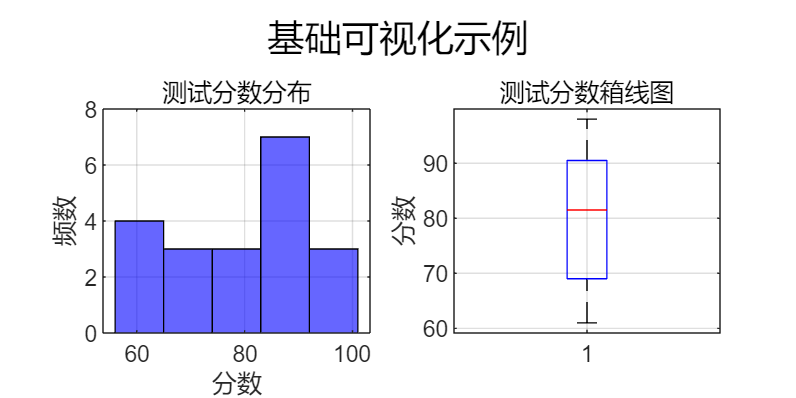


% 创建简单图表
figure('Position', [100, 100, 800, 400])

% 子图1：直方图
subplot(1, 2, 1)
histogram(test_scores, 5, 'FaceColor', 'blue', 'EdgeColor', 'black')
xlabel('分数')
ylabel('频数')
title('测试分数分布')
grid on

% 子图2：箱线图
subplot(1, 2, 2)
boxplot(test_scores)
ylabel('分数')
title('测试分数箱线图')
grid on

sgtitle('基础可视化示例', 'FontSize', 14)

## 第三部分：MATLAB实用技巧

% 9.1 向量化操作（避免循环）
disp(' ')

disp('=== MATLAB实用技巧 ===')

=== MATLAB实用技巧 ===


disp('技巧1：向量化操作（避免循环）')

技巧1：向量化操作（避免循环）



% 不好的做法（使用循环）
tic
result1 = zeros(size(clean_data2.Age));
for i = 1:length(clean_data2.Age)
    result1(i) = clean_data2.Age(i) * 2;
end
time_loop = toc;

% 好的做法（向量化）
tic
result2 = clean_data2.Age * 2;
time_vectorized = toc;

disp(['循环方法耗时：', num2str(time_loop), ' 秒'])

循环方法耗时：0.010168 秒


disp(['向量化方法耗时：', num2str(time_vectorized), ' 秒'])

向量化方法耗时：0.0015875 秒


disp(['加速比：', num2str(time_loop/time_vectorized)])

加速比：6.4053



% 9.2 匿名函数
disp(' ')

disp('技巧2：匿名函数')

技巧2：匿名函数



% 定义匿名函数
standardize = @(x) (x - mean(x)) / std(x);

% 使用匿名函数
standardized_age = standardize(clean_data2.Age);
disp(['标准化后的年龄（前5个值）：'])

标准化后的年龄（前5个值）：


disp(standardized_age(1:5)')

    1.7176    0.0128    0.0128   -0.5352    1.5350




% 9.3 数据分箱
disp(' ')

disp('技巧3：数据分箱')

技巧3：数据分箱



% 将年龄分为3组
age_bins = discretize(clean_data2.Age, [20, 40, 60, 80]);
bin_labels = {'青年', '中年', '老年'};

% 统计每组的数量
bin_counts = histcounts(age_bins, 1:4);
disp('年龄分组统计：')

年龄分组统计：


for i = 1:3
    disp([bin_labels{i}, ': ', num2str(bin_counts(i)), ' 人'])
end

青年: 34 人
中年: 40 人
老年: 26 人


## 总结


%  本节重点总结
disp(' ')

disp('=== 本节重点总结 ===')

=== 本节重点总结 ===


disp('1. 理解了三种基本数据类型：分类、顺序、数值')

1. 理解了三种基本数据类型：分类、顺序、数值


disp('2. 掌握了MATLAB的多种数据类型：数值、字符、逻辑、分类')

2. 掌握了MATLAB的多种数据类型：数值、字符、逻辑、分类


disp('3. 学会了使用MATLAB的数据结构：数组、矩阵、元胞数组、结构体、表格')

3. 学会了使用MATLAB的数据结构：数组、矩阵、元胞数组、结构体、表格


disp('4. 进行了基础操作练习：创建数据、矩阵运算、索引切片')

4. 进行了基础操作练习：创建数据、矩阵运算、索引切片


disp('5. 完成了简单统计和可视化')

5. 完成了简单统计和可视化



%  数据类型选择指南
disp(' ')

disp('=== 数据类型选择指南 ===')

=== 数据类型选择指南 ===


disp('在美赛中，根据数据特点选择合适的数据类型:')

在美赛中，根据数据特点选择合适的数据类型:


disp('1. 分类数据 → categorical 类型')

1. 分类数据 → categorical 类型


disp('2. 数值数据 → double 类型（默认）')

2. 数值数据 → double 类型（默认）


disp('3. 混合类型数据 → table 类型')

3. 混合类型数据 → table 类型


disp('4. 需要灵活存储 → cell 类型')

4. 需要灵活存储 → cell 类型


disp('5. 需要结构化存储 → struct 类型')

5. 需要结构化存储 → struct 类型


=== 下节预告 ===


下一节我们将深入学习:


1. 数据导入与清洗


2. 高级统计量计算


3. 复杂数据可视化


4. 实战案例：糖尿病数据分析


## 课后练习

%  基础练习
disp(' ')

disp('=== 课后练习 ===')

=== 课后练习 ===


disp('基础练习：')

基础练习：


disp('1. 创建一个包含姓名、年龄、成绩的学生表格')

1. 创建一个包含姓名、年龄、成绩的学生表格


disp('2. 计算年龄的平均值和标准差')

2. 计算年龄的平均值和标准差


disp('3. 按性别分组统计平均成绩')

3. 按性别分组统计平均成绩


disp('4. 绘制成绩的直方图')

4. 绘制成绩的直方图



%  进阶练习
disp(' ')

disp('挑战练习：')

挑战练习：


disp('1. 模拟一个班级30名学生的数据（姓名、性别、5科成绩）')

1. 模拟一个班级30名学生的数据（姓名、性别、5科成绩）


disp('2. 计算每个学生的平均分和总分')

2. 计算每个学生的平均分和总分


disp('3. 找出平均分最高的学生')

3. 找出平均分最高的学生


disp('4. 绘制各科成绩的箱线图比较')

4. 绘制各科成绩的箱线图比较



% 示例代码框架
disp(' ')

disp('示例代码框架：')

示例代码框架：



% 显示示例代码
example_code = [
    '% 1. 创建学生数据' newline ...
    'names = {"Student" + string(1:30)};' newline ...
    'genders = randi([0,1], 30, 1); % 0-女, 1-男' newline ...
    'scores = randi([60,100], 30, 5); % 5科成绩' newline ...
    newline ...
    '% 2. 创建表格' newline ...
    'student_data = table(names'', genders, scores, ...' newline ...
    '    ''VariableNames'', {''Name'', ''Gender'', ''Scores''});' newline ...
    newline ...
    '% 3. 计算统计量' newline ...
    '% 在这里添加你的代码...'
    ];

disp(example_code)

% 1. 创建学生数据
names = {"Student" + string(1:30)};
genders = randi([0,1], 30, 1); % 0-女, 1-男
scores = randi([60,100], 30, 5); % 5科成绩

% 2. 创建表格
student_data = table(names', genders, scores, ...
    'VariableNames', {'Name', 'Gender', 'Scores'});

% 3. 计算统计量
% 在这里添加你的代码...



% 清理工作区
% clearvars -except student_table  % 保留示例表格

disp(' ')

disp('=== 本节内容结束 ===')

=== 本节内容结束 ===


disp('请完成课后练习，下节课我们将检查并深入讲解！')

请完成课后练习，下节课我们将检查并深入讲解！
